# Question 1

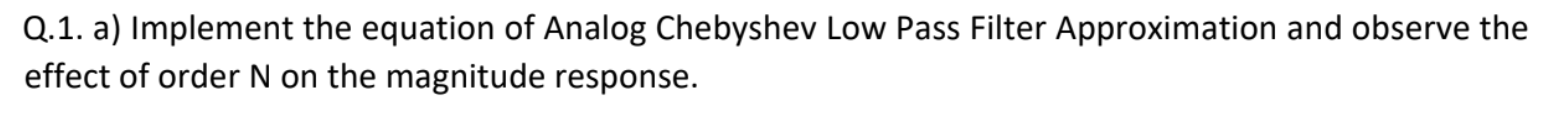

## chebyshev filter for different N

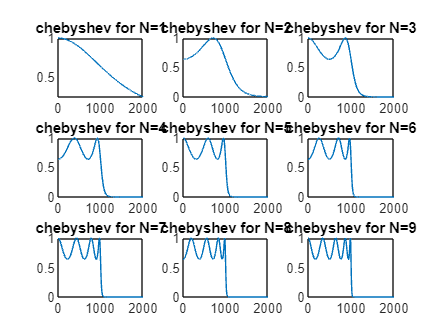

for N=1:9
n = 0:0.001:2;
Cn = ones(1,length(n));
e = 0.5;

for i = 1:length(n)
    if n(i)<=1
        Cn(i) = cos(N*acos(n(i)));
    else
        Cn(i) = cosh(N*acosh(n(i)));
    end
end 
H = 1./(1 + (e.^2).*(Cn.^2)).^2;
subplot(3,3,N)
plot(H)
title(['chebyshev for N=',num2str(N)])
end

## Poles of chebishev

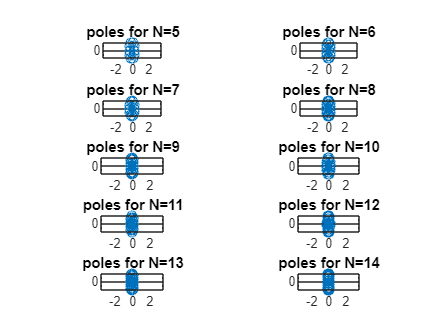

clf
for i = 5:14
syms k
N1 = i;

Ak = 1/N1*(2*k+1)*pi/2;
Bk = 1/N1*asinh(1/e);

sk = sin(Ak)*sinh(Bk) + 1j*cos(Ak)*cosh(Bk);

k_subs = 0:2*N1-1;
sk_subs = subs(sk, k, k_subs);

subplot(5,2,i-4)
stem(real(sk_subs),imag(sk_subs))
title(['poles for N=',num2str(N1)]) 
axis equal;
end